**The LQR on cart and pole system**

Consider the cart-and-pole system here depicted:

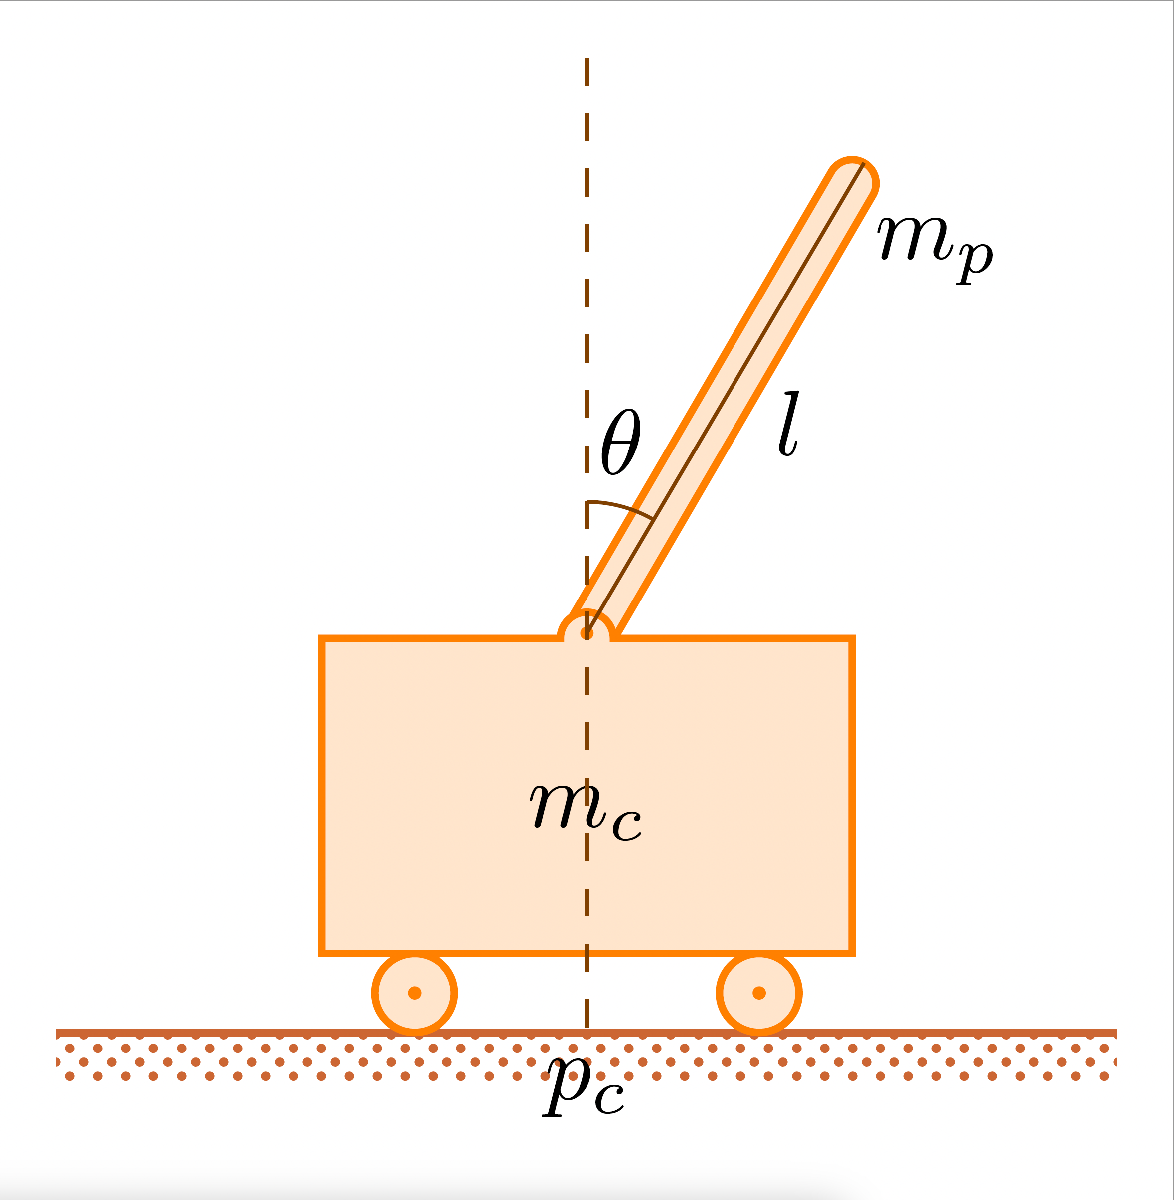

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient, and $F:|F|\leq 10\,\text{N}$ is the force applied to cart's center of mass.

1. Clearly define an optimal control problem for pole balancing.

**ANSWER 1:**

Let's consider the discrete-time dynamic system:


$$x^{\left(k+1\right)} =f\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)$$


OBS. 

We are dealing with a continuous-time system, so we will use the `c2d` function in MATLAB to obtain the corresponding discrete-time system.

Once we have obtained the discrete-time system, we would like to design a *state feedback controller *$\pi$ capable of returning $x^{\left(k\right)} =x_{\textrm{des}} \in X$ when $k\to +\infty$

Our **task**, i.e. the objective that must be achieved by the controller operating on the system, is to **"*****stabilise the pendulum in a vertical position"***, minimising the performance index.

DEF

Let's define the performance index:

Be $h:X\times U\to R$ the so-called ***objective function*** s.t. 


$$J=\sum_{k=0}^{+\infty } h\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)$$


is the ***performance index*** that evaluates the state-action pair over an infinite time horizon

DEF

 The general definition of $J$ for optimal control problems is as follows


$$J=\sum_{k=0}^{+\infty } {x^{\left(k\right)} }^T {\textrm{Qx}}^{\left(k\right)} +u^{{\left(k\right)}^T } {\textrm{Ru}}^{\left(k\right)}$$


s.t.    $\begin{array}{l}
x^{\left(k+1\right)} ={\textrm{Ax}}^{\left(k\right)} +{\textrm{Bu}}^{\left(k\right)} \\
x^{\left(0\right)} =x_{\textrm{ini}} \;,x^{\left(\infty \right)} \to 0
\end{array}$

where:

- **Q: State term**; penalises the deviation of the state $x\left(t\right)$ from the origin (or from a reference point). A high Q value means that you want the state to converge quickly and accurately to the desired value, i.e. it penalises the state error.

- **R: Control Term**; penalises the energy of the control signal $u\left(t\right)$. A high R value means that you want to use as little energy as possible for the actuator, i.e. it penalises the ‘cost’ of control.

The objective, therefore, is to calculate the *optimal controller* $\pi^* \left(x^{\left(k\right)} \right)$ by solving the following optimal control problem:


$$\pi^* =\underset{\pi }{\textrm{argmin}} \;J$$


OBS.

Since we are studying an infinite horizon, to solve the problem we will refer to the:

***‘Fundamental Theorem of Infinite-Time Quadratic Linear Optimal Control’***

 which states the following:

Find $\pi^* \left(x^{\left(k\right)} \right)=-{\textrm{Kx}}^{\left(k\right)}$ solution of:


$$\underset{\pi }{\textrm{argmin}} \sum_{k=0}^{+\infty } x^{{\left(k\right)}^T } {\textrm{Qx}}^{\left(k\right)} +u^{{\left(k\right)}^T } Ru^{\left(k\right)}$$


s.t. $\begin{array}{l}
x^{\left(k+1\right)} ={\textrm{Ax}}^{\left(k\right)} +{\textrm{Bu}}^{\left(k\right)} \\
x^{\left(k\right)} =x_{\textrm{ini}} \;,x^{\left(\infty \right)} \to 0
\end{array}$

with the following assumptions: $\begin{array}{l}
Q=Q^T \ge 0\;,R=R^T >0\\
\left(A,C\right)\;\mathrm{is}\;\mathrm{observable}\\
\left(A,B\right)\;\mathrm{is}\;\mathrm{reachable}
\end{array}$

2. Is the LQR applicable in its simple form on the system? If not what is missed?

**ANSWER 2:**

In this case, LQR is not applicable in its simple form because it has two limitations:

- the system must be **linear**, so it is not possible to apply LQR directly to our system; it must first be linearised around the equilibrium point.

- The system must be **discretised**, because we will be working in discrete time and the system given in the exercise is described in continuous time.

3. Design an LQR for the linearized version of the cart and pole obtained in the previous hands-on. Justify all the design choices and perform all the required checks

**ANSWER 3:**

To linearise the system around equilibrium, we will copy and paste parts of the MATLAB code from the previous hands-on exercise. Specifically, we will present code that can:

- define the **state equations**, then the state and input domains (as required in the first point of hands-on 1)

- calculate the **equilibrium point** taking into account the previously defined domains (as required in the second point of hands-on 1)

- **linearise the non-linear system** around the equilibrium point (as required in the fourth point of hands-on 1)

**IMPORTANT NOTE:**

To have cleaner code, in this hands-on **we will** **not** **consider the limits** on state variables imposed in the previous hands-on. From a conceptual and graphical point of view, nothing changes, except that we will have systems that will not be interrupted during their simulation, thus presenting graphical representations over a longer time interval. This decision was made because the objective of this HandsOn is not to see when the system goes out of bounds, but to try to control the system in order to balance the pendulum, minimising the performance index.

% --- MATLAB code taken from POINT 1 of HandsOn1 ---
clear 
close all
clc

% we define VARIABLES and PARAMETERS through SYMBOLIC declaration
syms theta theta_1 p_c p_c_1 p_0
syms g m_c m_p l mu_c mu_p  F

% theta, theta_1 = angle and angular velocity of the pole
% p_c, p_c_1 = position and velocity of the cart
% theta_2, p_c_2 = accelerations appearing in the equations of state

% m_c = cart mass
% m_p = pole mass
% l = half arm length
% g = acceleration due to gravity
% mu_c = cart friction
% mu_p = pole friction
% u = input (i.e. force F)
% p_0 = initial cart position

% expressions of theta_2 and p_c_2
theta_2 = ( g*sin(theta)+cos(theta)*((-F-m_p*l*(theta_1^2)*sin(theta)+mu_c*sign(p_c_1))/(m_c+m_p))-(mu_p*theta_1)/(m_p*l) ) / ( l * ((4/3)-(m_p*(cos(theta)^2))/(m_c+m_p) ));
p_c_2 = ( F+m_p*l*((theta_1^2)*sin(theta)-(theta_2)*cos(theta))-mu_c*sign(p_c_1) )/ (m_c+m_p);

% --- definition of STATE and INPUT VECTOR, and related DOMAINS ---
x = [theta ; theta_1 ; p_c ; p_c_1];
u = F;

% X = { (theta, theta_1, p_c, p_c_1)' : |theta| <= pi/2, |theta_1| <= 20, |p_c| <= 3, |p_c_1| <= 5 }
% OBS. --> in particular, we limit the angle of the pole so that it can
%          only move pi/2 from the centre, i.e. from when it is in a straight position
assume(abs(theta) <= pi/2);
assume(abs(theta_1) <= 20);
assume(abs(p_c) <= 3);
assume(abs(p_c_1) <= 5);

% U = { u ∈ R : u ∈ [-10, +10] }
% OBS. --> the domain of the control input is defined in the exercise text
assume(abs(F)<=10);  

% --- MATLAB code taken from POINT 2 of HandsOn1 ---

% we define the parameters theta_2_par and p_c_2_par
theta_2_par = subs(theta_2, [g, m_c, m_p, l, mu_c, mu_p], [9.8, 1, 0.1, 0.5, 0.0005, 0.000002]);
p_c_2_par = subs(p_c_2, [g, m_c, m_p, l, mu_c, mu_p], [9.8, 1, 0.1, 0.5, 0.0005, 0.000002]);

% we impose the condition of EQUILIBRIUM, i.e. all DERIVATIVES are ZERO and u = 0
theta_2_eq = subs(theta_2_par, [p_c_1, theta_1, p_c_2, F], [0, 0, 0, 0]);
p_c_2_eq = subs(p_c_2_par, [p_c_1, theta_1, theta_2, F], [0, 0, 0, 0]);

% let's simplify
theta_2_eq = simplify(theta_2_eq);
p_c_2_eq = simplify(p_c_2_eq);

% let's impose theta_2_eq == 0 and solve for theta.
theta_sol = solve(theta_2_eq == 0, theta, "ReturnConditions", true) 

theta_sol = struct with fields:
         theta: pi*z1
    parameters: z1
    conditions: sin(pi*z1) ~= -(3^(1/2)*41^(1/2)*1i)/3 & sin(pi*z1) ~= (3^(1/2)*41^(1/2)*1i)/3 & z1 == 0


As discussed in the previous HandsOn, we obtain a single admissible equilibrium point with state dominance, namely:

$\bar{x} =\left\lbrack \begin{array}{c}
0\\
0\\
p_0 \\
0
\end{array}\right\rbrack$    with    $p_0 \in R\;\textrm{such}\;\textrm{that}\;{|p}_0 |\le 1$

Let's, therefore, consider the **unstable equilibrium point** corresponding to:


$$\left(\bar{x} ,\bar{u} \right)\;\;\textrm{such}\;\textrm{that}\;\;\bar{x} ={\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0
\end{array}\right\rbrack }^T \;;\;\bar{u} =0$$


and to define the linearised system around this equilibrium.

OBS.

As the initial position of the cart, we considered $p_0 =0$

% let's define the PHYSICAL PARAMETERS
par.g = 9.8;           % Acceleration due to gravity (m/s^2)
par.m_c = 1.0;         % Mass of the cart (kg)
par.m_p = 0.1;         % Mass of the pole (kg)
par.l = 0.5;           % Half the length of the pole (m)
par.mu_c = 0.0005;     % Cart friction
par.mu_p = 0.000002;   % Pole friction

% let us define the CONTROL INPUTS
N = 100;               % Number of control inputs to apply  

% CALCULATION OF JACOBIAN MATRICES

% x = [theta ; theta_1 ; p_c ; p_c_1];
% u = F;

% Let us define the state function f(x,u)

% NOTE --> for linearisation, we ignore friction (mu_c, mu_p)
%          because the sign() term is not differentiable at the origin.
theta_2_lin = ( g*sin(theta)+cos(theta)*((-F-m_p*l*(theta_1^2)*sin(theta))/(m_c+m_p))) / ( l * ((4/3)-(m_p*(cos(theta)^2))/(m_c+m_p) ));
p_c_2_lin = ( F+m_p*l*((theta_1^2)*sin(theta)-(theta_2_lin)*cos(theta)) ) / (m_c+m_p);

f = [theta_1; theta_2_lin; p_c_1; p_c_2_lin];

% We calculate the Jacobian matrices A and B in symbolic form.
A_sym = jacobian(f, x);
B_sym = jacobian(f, F);

% Equilibrium point: x_bar = [0; 0; 0; 0], u_bar = 0
x_bar = [0; 0; 0; 0];
u_bar = 0;

% Let us substitute the numerical values of the parameters (par) and the equilibrium point
A_num = subs(A_sym, [g, m_c, m_p, l], [par.g, par.m_c, par.m_p, par.l]);
A_num = double(subs(A_num, [x; F], [x_bar; u_bar]));

B_num = subs(B_sym, [g, m_c, m_p, l], [par.g, par.m_c, par.m_p, par.l]);
B_num = double(subs(B_num, [x; F], [x_bar; u_bar]));

% CREATION OF THE LINEAR MODEL
C = eye(4);
D = zeros(4,1);

% LINEAR SYSTEM obtained from linearisation around equilibrium
sys_lin = ss(A_num, B_num, C, D);

4. Simulate the linearized cart and pole system controlled by an LQR. Plot the significant behaviors

**ANSWER 4:**

First, we will discretise the continuous-time linearised system using a MATLAB function `c2d`.

Next, we will verify that the assumptions of the *Fundamental Theorem of Infinite-Time Quadratic Linear Optimal Control* are true, so we will use the following function in MATLAB


$$\mathrm{dlqr}\left(A,B,Q,R\right)$$


This function calculates:

- `K`: optimal gain matrix

- `P`: matrix associated with *Riccati's algebraic equation*

- `CLeig`: eigenvalues of the closed-loop system

Once this is done, we will be able to show the behaviour of the linearised cart-and-pole system around equilibrium, controlled through LQR.

OBS.

The animations only show the last moment of the simulation. To view the entire simulation, open the corresponding **mp4 files**, which are indicated below each animation.

% Let's define the system, first in CONTINUOUS TIME
LTIsys_tc = ss(A_num, B_num, C, D);

% time interval
Ts = 0.05;
t_start = 0;
t_end = Ts*N;
t = (t_start:Ts:(t_end-Ts))';

% therefore in DISCRETE TIME
LTIsys_td = c2d(LTIsys_tc, Ts);

% Let's save A and B from discrete time
Ad = LTIsys_td.A;
Bd = LTIsys_td.B;

% objective function parameters
Q=1*eye(4);
R=1;

% % control of REACHABILITY
if (rank(ctrb(Ad,Bd))==size(Ad)) 
    disp("System fully reachable");
else
    disp("System not fully reachable");
end

System fully reachable



% control of OBSERVABILITY
[UQ,SQ,VQ] = svd(Q); 
Cq = UQ*SQ^.5;

if (rank(obsv(Ad,Cq))==size(Ad)) 
    disp("System fully observable");
else
    disp("System not fully observable");
end

System fully observable



% We use dlqr to find:
%       K --> optimal gain matrix
%       P --> solution matrix of Riccati's algebraic equation
%       CLeig --> closed-loop eigenvalues
[K,Pbar,CLeig] = dlqr(Ad,Bd,Q,R);

% Let's define a buffer for the state vector and one for the control input.
x_cl = zeros(4,N);
u_cl = zeros(N,1);

% save the initial conditions --> as in HandsOn1, we study three different cases:
%                                    CASE A) x0 = [0.05; 0; 0; 0]
%                                    CASE B) x0 = [0.20; 0; 0; 0]
%                                    CASE C) x0 = [0.60; 0; 0; 0]
x0_A = [0.05; 0; 0; 0];
x0_B = [0.20; 0; 0; 0];
x0_C = [0.60; 0; 0; 0];

`CASO A) ``x0 = [0.05; 0; 0; 0]`

x_cl_A = x_cl;
x_cl_A(:,1) = x0_A;


% CONTROL INPUT and CLOSED-LOOP system
for k = 1:N-1
    u_cl(k,1) = -K*x_cl_A(:,k);
    x_cl_A(:,k+1) = Ad*x_cl_A(:,k)+Bd*u_cl(k);
end

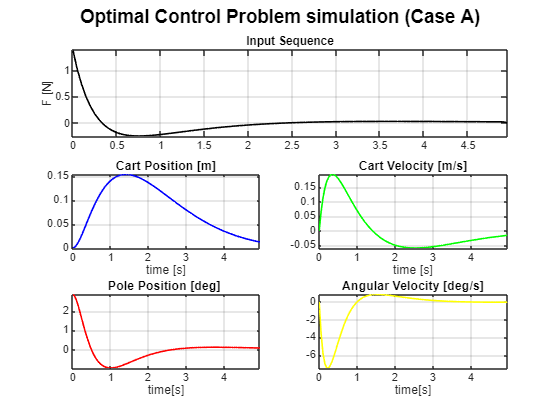

% Optimal Control Problem simulation --> CASE A
figure;
sgtitle('Optimal Control Problem simulation (Case A)', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t, u_cl, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t, x_cl_A(3,:), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t, x_cl_A(4,:), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t, rad2deg(x_cl_A(1,:)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t, rad2deg(x_cl_A(2,:)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_OCP_A ...
Video saved as: animation_OCP_A


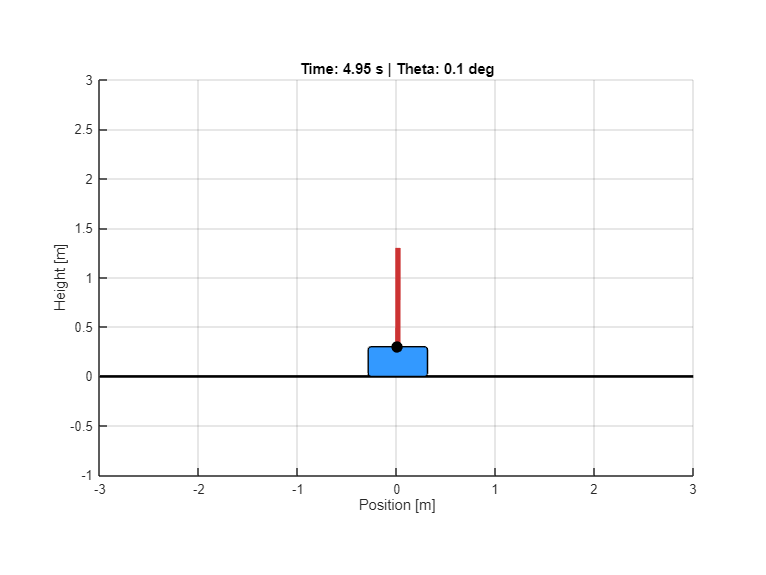

% Optimal Control Problem animation--> case A
animazione_test(x_cl_A, par, Ts, 'animation_OCP_A');

`CASO B) ``x0 = [0.20; 0; 0; 0]`

x_cl_B = x_cl;
x_cl_B(:,1) = x0_B;

% reset the closed-loop control input
u_cl = zeros(N,1);

% CONTROL INPUT and CLOSED-LOOP system
for k = 1:N-1
    u_cl(k,1) = -K*x_cl_B(:,k);
    x_cl_B(:,k+1) = Ad*x_cl_B(:,k)+Bd*u_cl(k);
end

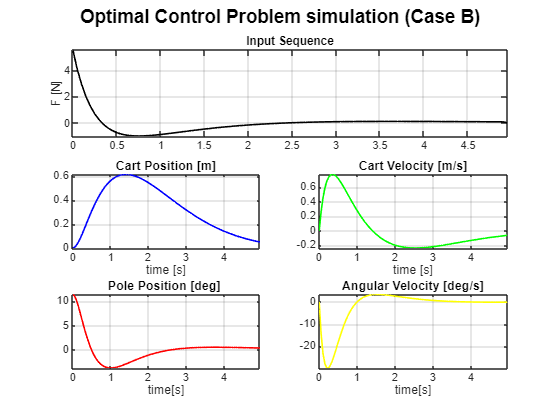

% Optimal Control Problem simulation --> CASE B
figure;
sgtitle('Optimal Control Problem simulation (Case B)', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t, u_cl, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t, x_cl_B(3,:), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t, x_cl_B(4,:), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t, rad2deg(x_cl_B(1,:)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t, rad2deg(x_cl_B(2,:)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_OCP_B ...
Video saved as: animation_OCP_B


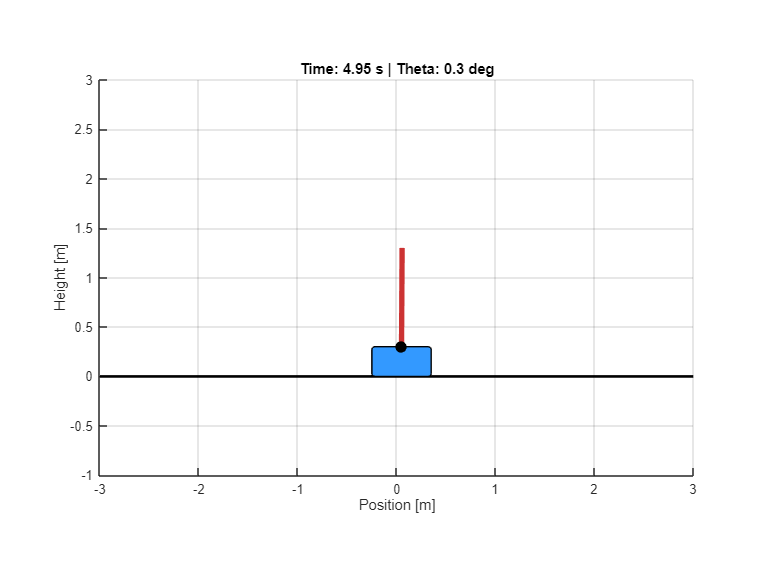

% Optimal Control Problem animation --> case B
animazione_test(x_cl_B, par, Ts, 'animation_OCP_B');

`CASO C) ``x0 = [0.60; 0; 0; 0]`

x_cl_C = x_cl;
x_cl_C(:,1) = x0_C;

% reset the closed-loop control input
u_cl = zeros(N,1);

% CONTROL INPUT and CLOSED-LOOP system
for k = 1:N-1
    u_cl(k,1) = -K*x_cl_C(:,k);
    x_cl_C(:,k+1) = Ad*x_cl_C(:,k)+Bd*u_cl(k);
end

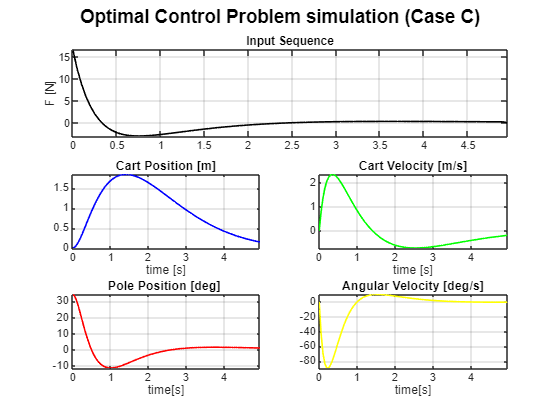

% Optimal Control Problem simulation --> CASE C
figure;
sgtitle('Optimal Control Problem simulation (Case C)', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t, u_cl, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t, x_cl_C(3,:), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t, x_cl_C(4,:), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t, rad2deg(x_cl_C(1,:)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t, rad2deg(x_cl_C(2,:)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_OCP_C ...
Video saved as: animation_OCP_C


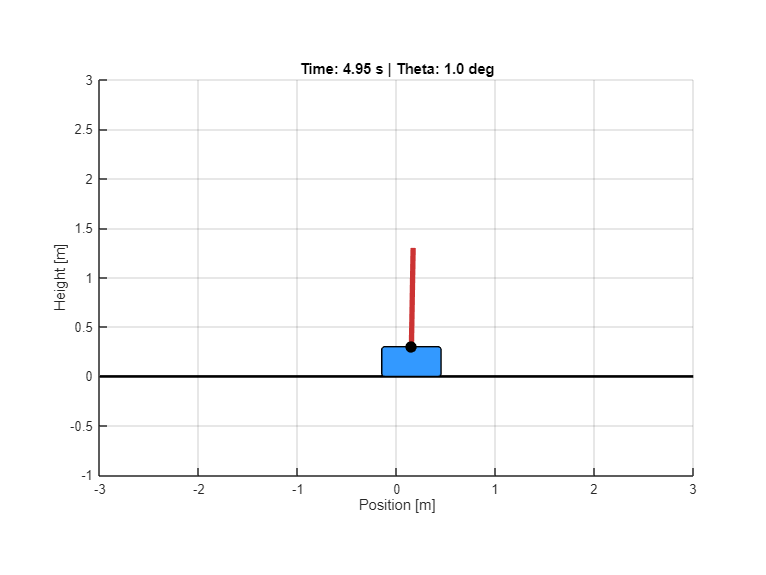

% Optimal Control Problem animation --> case C
animazione_test(x_cl_C, par, Ts, 'animation_OCP_C');

OBS.

We note that in the first few moments, the required input exceeds the limits of the actuator. In a real-world scenario, this would lead to saturation. However, in this exercise, we analyse the stabilisation properties of the LQR without explicit constraints (as explained above).

5. Simulate the non-linear cart and pole system controlled by the previously obtained LQR. Plot the significant behaviors

**ANSWER 5:**

Since we must consider the non-linear system, we use the gain matrix $K$ previously obtained to calculate the control input to be applied to our non-linear system, as follows:


$$u\left(k\right)=-K\left(x\left(k\right)-\bar{x} \right)+\bar{u}$$


% Let's define a buffer for the state vector and one for the control input:
x_cl_NL = zeros(4,N);
u_cl_NL = zeros(N,1);

% options for ode45 --> comment in HandsOn1
opts = odeset('RelTol',1e-6,'AbsTol',1e-8); 

`CASO A) ``x0 = [0.05; 0; 0; 0]`

% save the initial conditions for each case
x_cl_NL_A(:,1) = x0_A;
u_cl_NL_A = u_cl_NL;

% CONTROL INPUT and CLOSED-LOOP system
for k = 1:N-1
    
    % control input for the current interval
    u_cl_NL_A(k,1) = -K*(x_cl_NL_A(:,k)-x_bar) + u_bar;
    par.F = u_cl_NL_A(k,1);

    % we define a time interval for each iteration
    t_start = (k-1)*Ts;
    t_end = k*Ts;
    t_span = linspace(t_start, t_end);

    % we perform the simulation for the k-th segment
    [t_k, x_k] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x_cl_NL_A(:,k), opts);
   
    % once the simulation is complete, we update the initial state and then move on to the next iteration.
    x_cl_NL_A(:,k+1) = x_k(end,:)';

end

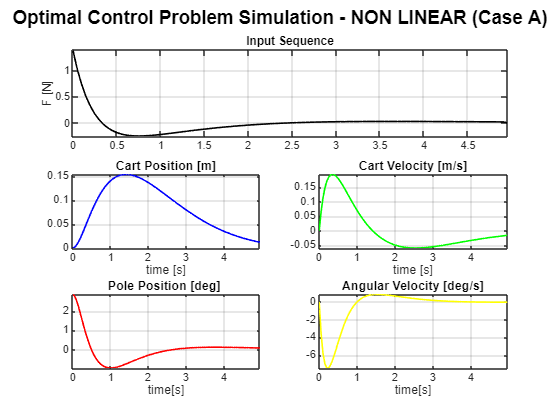

% Optimal Control Problem Simulation - NON LINEAR --> CASE A
figure;
sgtitle('Optimal Control Problem Simulation - NON LINEAR (Case A)', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t, u_cl_NL_A, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t, x_cl_NL_A(3,:), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t, x_cl_NL_A(4,:), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t, rad2deg(x_cl_NL_A(1,:)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t, rad2deg(x_cl_NL_A(2,:)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_OCP_NL_A ...
Video saved as: animation_OCP_NL_A


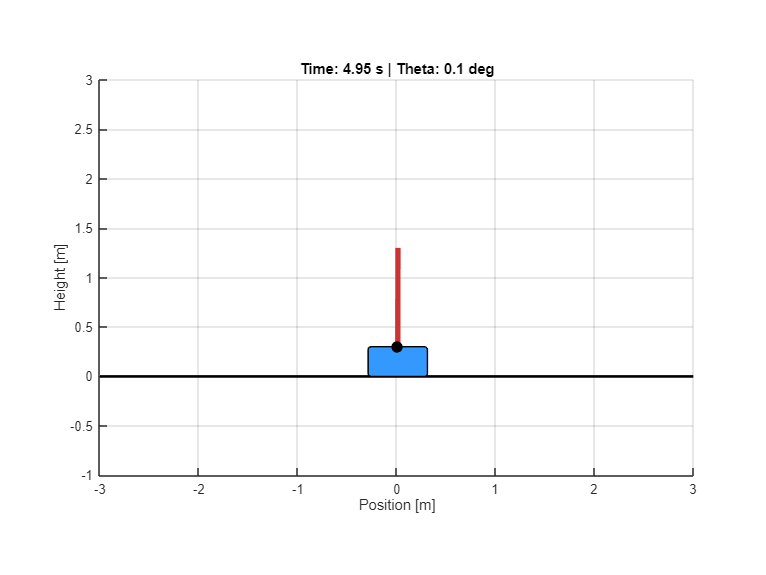

% Optimal Control Problem animation - NON LINEAR --> case A
animazione_test(x_cl_NL_A, par, Ts, 'animation_OCP_NL_A');

`CASO B) ``x0 = [0.20; 0; 0; 0]`

% save the initial conditions
x_cl_NL_B(:,1) = x0_B;

% we reset the closed loop control input
u_cl_NL_B = zeros(N,1);

% CONTROL INPUT and CLOSED-LOOP system
for k = 1:N-1
    
    % control input for the current interval
    u_cl_NL_B(k,1) = -K*(x_cl_NL_B(:,k)-x_bar) + u_bar;
    par.F = u_cl_NL_B(k,1);

    % we run the simulation for the k-th segment
    [t_k, x_k] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x_cl_NL_B(:,k), opts);
   
    % once the simulation is complete, we update the initial state and then move on to the next iteration.
    x_cl_NL_B(:,k+1) = x_k(end,:)';

end

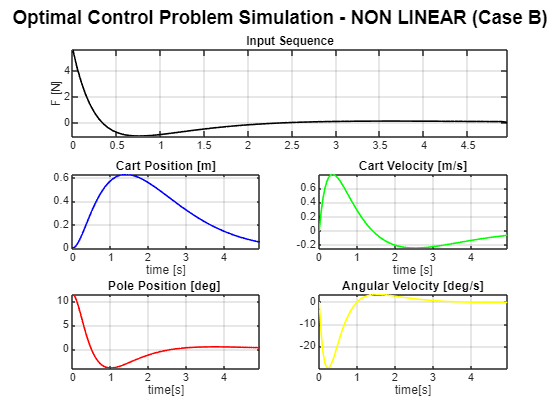

% Optimal Control Problem Simulation - NON LINEAR --> CASE B
figure;
sgtitle('Optimal Control Problem Simulation - NON LINEAR (Case B)', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t, u_cl_NL_B, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t, x_cl_NL_B(3,:), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t, x_cl_NL_B(4,:), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t, rad2deg(x_cl_NL_B(1,:)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t, rad2deg(x_cl_NL_B(2,:)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_OCP_NL_B ...
Video saved as: animation_OCP_NL_B


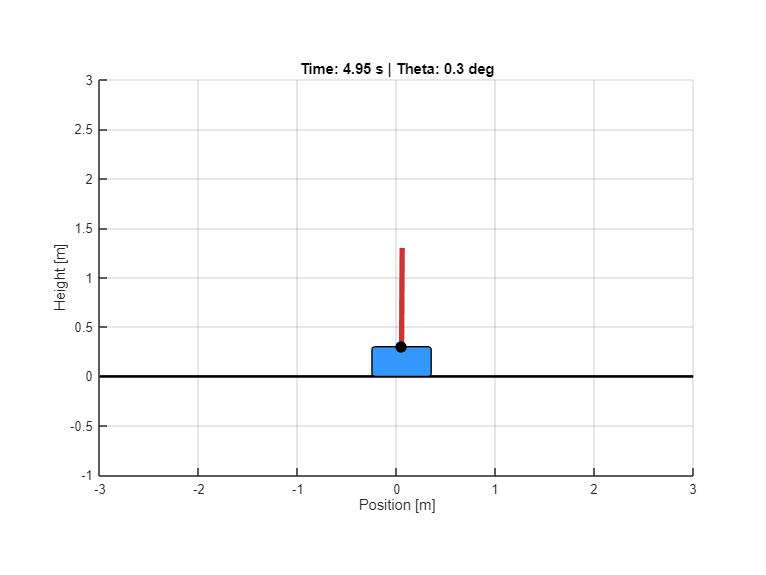

% Optimal Control Problem animation - NON LINEAR --> case B
animazione_test(x_cl_NL_B, par, Ts, 'animation_OCP_NL_B');

`CASO C) ``x0 = [0.60; 0; 0; 0]`

% let's save the initial conditions for each case
x_cl_NL_C(:,1) = x0_C;

% we reset the closed loop control input
u_cl_NL_C = zeros(N,1);

% CONTROL INPUT and CLOSED-LOOP system
for k = 1:N-1
    
    % control input for the current interval
    u_cl_NL_C(k,1) = -K*(x_cl_NL_C(:,k)-x_bar) + u_bar;
    par.F = u_cl_NL_C(k,1);

    % we perform the simulation for the k-th segment
    [t_k, x_k] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x_cl_NL_C(:,k), opts);
   
    % once the simulation is complete, we update the initial state and then move on to the next iteration.
    x_cl_NL_C(:,k+1) = x_k(end,:)';

end

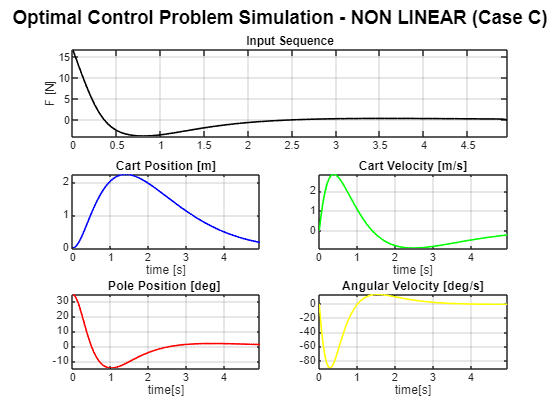

% Optimal Control Problem Simulation - NON LINEAR --> CASE C
figure;
sgtitle('Optimal Control Problem Simulation - NON LINEAR (Case C)', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t, u_cl_NL_C, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t, x_cl_NL_C(3,:), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t, x_cl_NL_C(4,:), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t, rad2deg(x_cl_NL_C(1,:)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t, rad2deg(x_cl_NL_C(2,:)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_OCP_NL_C ...
Video saved as: animation_OCP_NL_C


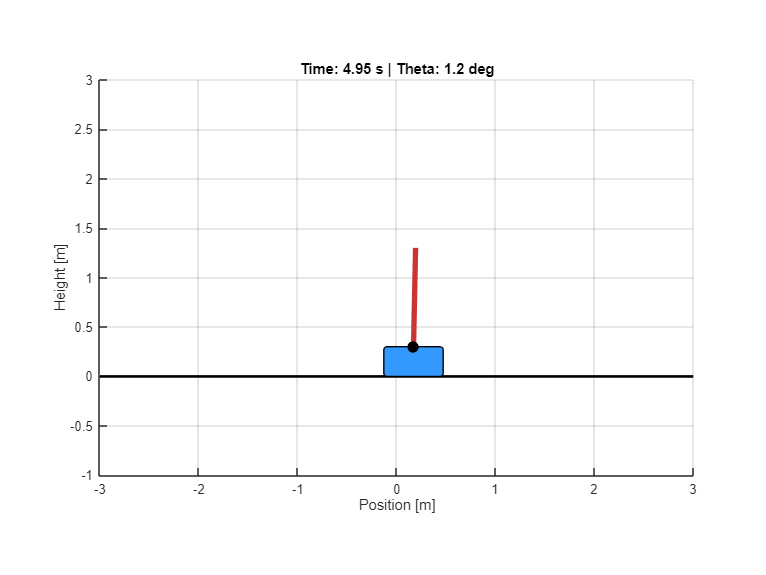

% animazione --> caso C
animazione_test(x_cl_NL_C, par, Ts, 'animation_OCP_NL_C');

6. Comment results obtained in the two simulations

**ANSWER 6:**

Let's **compare** the results obtained in the non-linear system (*continuous line*) with those of the linearised system (*dotted line*) around the equilibrium point $\left(\bar{x} ,\bar{u} \right)$ starting from the initial conditions closest to equilibrium, i.e. those of case A, then moving on to case B, and then to case C.

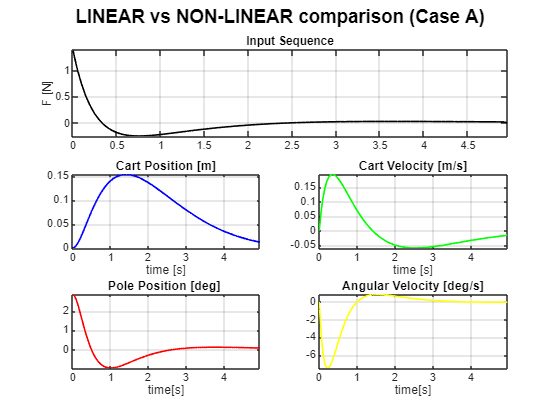

% LINEAR vs NON-LINEAR comparison --> CASE A
figure;
sgtitle('LINEAR vs NON-LINEAR comparison (Case A)', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t, u_cl_NL_A, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t, x_cl_NL_A(3,:), 'b', 'LineWidth', 1.2);
hold on;
plot(t, x_cl_A(3,:), 'b--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t, x_cl_NL_A(4,:), 'g', 'LineWidth', 1.2); 
hold on;
plot(t, x_cl_A(4,:), 'g--', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t, rad2deg(x_cl_NL_A(1,:)), 'r', 'LineWidth', 1.2); 
hold on;
plot(t, rad2deg(x_cl_A(1,:)), 'r--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t, rad2deg(x_cl_NL_A(2,:)), 'y', 'LineWidth', 1.2); 
hold on;
plot(t, rad2deg(x_cl_A(2,:)), 'y--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

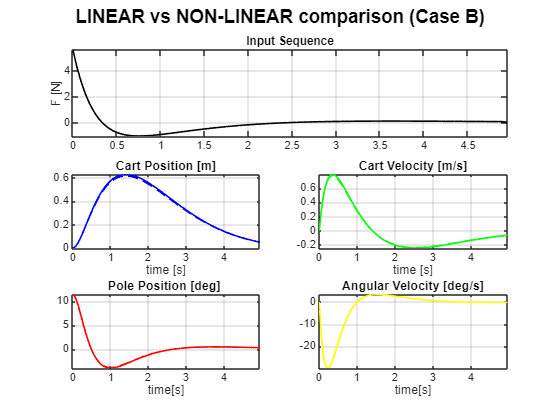


% LINEAR vs NON-LINEAR comparison --> CASE B
figure;
sgtitle('LINEAR vs NON-LINEAR comparison (Case B)', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t, u_cl_NL_B, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t, x_cl_NL_B(3,:), 'b', 'LineWidth', 1.2);
hold on;
plot(t, x_cl_B(3,:), 'b--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t, x_cl_NL_B(4,:), 'g', 'LineWidth', 1.2); 
hold on;
plot(t, x_cl_B(4,:), 'g--', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t, rad2deg(x_cl_NL_B(1,:)), 'r', 'LineWidth', 1.2); 
hold on;
plot(t, rad2deg(x_cl_B(1,:)), 'r--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t, rad2deg(x_cl_NL_B(2,:)), 'y', 'LineWidth', 1.2); 
hold on;
plot(t, rad2deg(x_cl_B(2,:)), 'y--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

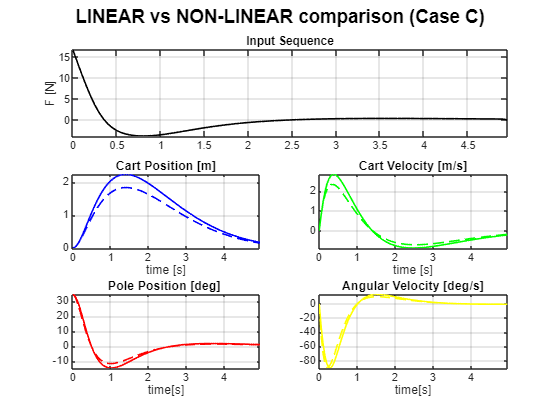


% LINEAR vs NON-LINEAR comparison --> CASE C
figure;
sgtitle('LINEAR vs NON-LINEAR comparison (Case C)', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t, u_cl_NL_C, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t, x_cl_NL_C(3,:), 'b', 'LineWidth', 1.2);
hold on;
plot(t, x_cl_C(3,:), 'b--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t, x_cl_NL_C(4,:), 'g', 'LineWidth', 1.2); 
hold on;
plot(t, x_cl_C(4,:), 'g--', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t, rad2deg(x_cl_NL_C(1,:)), 'r', 'LineWidth', 1.2); 
hold on;
plot(t, rad2deg(x_cl_C(1,:)), 'r--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t, rad2deg(x_cl_NL_C(2,:)), 'y', 'LineWidth', 1.2); 
hold on;
plot(t, rad2deg(x_cl_C(2,:)), 'y--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

OBS.

Three important considerations emerge from this comparison:

- **Validity of the linear approximation**: in case A (where we have an initial condition close to equilibrium), the trajectories of the linear and non-linear systems are almost perfectly superimposed. This confirms that for small perturbations, the linearised system accurately describes the dynamics of the system. In case C (where we have an initial condition further from equilibrium), the curves diverge more significantly.

- **Robustness of feedback control**: although the controller $K$ was designed on an “ideal” model (the linearised model is an approximation of the real system), the non-linear system is still stabilised asymptotically $\left(x\to 0\;\mathrm{per}\;t\to \infty \right)$.

- **Effect of control energy**: observing the input trajectory $u$, we note that in order to stabilise the system starting from more disturbed initial conditions (case C), the controller requires a high initial control effort. If we had introduced constraints on the input, i.e. actuator saturation in the simulation, we would have noticed a slowdown in convergence as the system would not have been able to deliver the “required” force calculated by the LQR. We show this case below, presenting a  *continuous line* for the constrained case and a *dotted line* for the unconstrained case:

% save the initial conditions for each case
x_cl_NL_C_vincolato(:,1) = x0_C;

% reset the closed loop control input
u_cl_NL_C_vincolato = zeros(N,1);

% CONTROL INPUT and CLOSED-LOOP system
for k = 1:N-1
    
    % control input for the current interval
    u_cl_NL_C_vincolato(k,1) = -K*(x_cl_NL_C_vincolato(:,k)-x_bar) + u_bar;

    if u_cl_NL_C_vincolato(k,1) > 10
       u_cl_NL_C_vincolato(k,1) = 10;
       par.F = u_cl_NL_C_vincolato(k,1);
    elseif u_cl_NL_C_vincolato(k,1) < -10
       u_cl_NL_C_vincolato(k,1) = -10;
       par.F = u_cl_NL_C_vincolato(k,1);
    else
       par.F = u_cl_NL_C_vincolato(k,1);
    end

    % we perform the simulation for the k-th segment
    [t_k, x_k] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x_cl_NL_C_vincolato(:,k), opts);
   
    % once the simulation is complete, we update the initial state and then move on to the next iteration.
    x_cl_NL_C_vincolato(:,k+1) = x_k(end,:)';

end

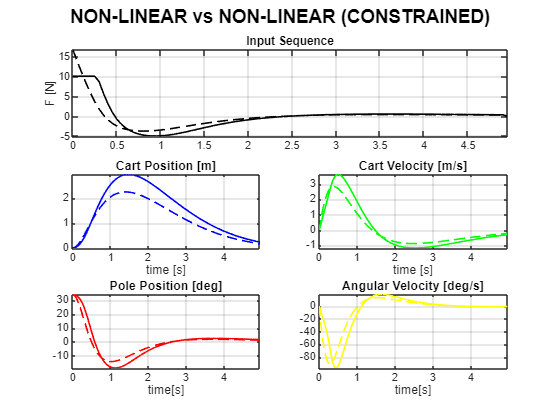

% Optimal Control Problem NON LINEAR vs NON LINEAR (CONSTRAINED)  --> CASE C
figure;
sgtitle('NON-LINEAR vs NON-LINEAR (CONSTRAINED)', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t, u_cl_NL_C_vincolato, 'k', 'LineWidth', 1.2);
hold on;
plot(t, u_cl_NL_C, 'k--', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t, x_cl_NL_C_vincolato(3,:), 'b', 'LineWidth', 1.2); 
hold on;
plot(t, x_cl_NL_C(3,:), 'b--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t, x_cl_NL_C_vincolato(4,:), 'g', 'LineWidth', 1.2); 
hold on;
plot(t, x_cl_NL_C(4,:), 'g--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t, rad2deg(x_cl_NL_C_vincolato(1,:)), 'r', 'LineWidth', 1.2); 
hold on;
plot(t, rad2deg(x_cl_NL_C(1,:)), 'r--', 'LineWidth', 1.2);
xlabel('time[s]'); title('Pole Position [deg]');
grid on;
axis tight;

subplot(3,2,6);
plot(t, rad2deg(x_cl_NL_C_vincolato(2,:)), 'y', 'LineWidth', 1.2);
hold on;
plot(t, rad2deg(x_cl_NL_C(2,:)), 'y--', 'LineWidth', 1.2);
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

**NOTE:**

*Local Functions* used in the above code, presented with appropriate comments:

% --- LOCAL FUNCTION ---
% % 1. dinamica_nonLineare() --> allows us to calculate x_dot, through the implementation
%                                of the nonlinear differential equations of the Cart-and-Pole system. 
%                                The parameters we will pass are:
%                                   - t, not used explicitly in the function, is used to call ode()
%                                   - x, state vector [4x1]
%                                   - par, a structure containing all useful parameters

function dxdt = dinamica_nonLineare(t, x, par)

% extraction of parameters and state
g = par.g;
m_c = par.m_c;
m_p = par.m_p;
l = par.l;
mu_c = par.mu_c;
mu_p = par.mu_p;
F = par.F;

theta    = x(1);
theta_1  = x(2);
p_c      = x(3);
p_c_1    = x(4);

% we therefore define theta_2 and p_c_2
theta_2 = ( g*sin(theta)+cos(theta)*((-F-m_p*l*(theta_1^2)*sin(theta)+mu_c*sign(p_c_1))/(m_c+m_p))-(mu_p*theta_1)/(m_p*l) ) / ( l * ((4/3)-(m_p*(cos(theta)^2))/(m_c+m_p) ));
p_c_2 = ( F+m_p*l*((theta_1^2)*sin(theta)-(theta_2)*cos(theta))-mu_c*sign(p_c_1) )/ (m_c+m_p);


% let's define the derivative vector dxdt
% dxdt = [theta_1; theta_2; p_c_1; p_c_2]
dxdt = zeros(4, 1);

dxdt(1) = theta_1;
dxdt(2) = theta_2;
dxdt(3) = p_c_1;
dxdt(4) = p_c_2;

end

% % 2. animazione_test() --> allows us to describe the animation of the cart-and-pole system, 
%                            thus providing visual support in addition to the graphs.
%                            It only shows the last moment in time, but this function allows us to save the various frames
%                            in a video, so that we can see the entire simulation
%                            The parameters we pass to it are:
%                               - stati, a vector containing all states 
%                               - par, a struct containing all useful parameters
%                               - Ts, sampling time
%                               - video_filename, the name we saved the video file with

function animazione_test(stati, par, Ts, video_filename)
    
    % graphical parameters
    L = 2 * par.l;          
    W_cart = 0.6;           
    H_cart = 0.3;           
    
    % let's create the figure
    h_fig = figure('Name', 'Animazione Cart-Pole', 'Color', 'w');
    set(h_fig, 'Position', [100, 100, 800, 600]); 
    clf;
    hold on;
    grid on;
    axis equal;
    xlim([-3, 3]);          
    ylim([-1, 3]); 

    % let's create the 'floor'
    line([-3, 3], [0, 0], 'Color', 'k', 'LineWidth', 2);

    % create a video file in the current folder
    v = VideoWriter(video_filename, 'MPEG-4');
    v.FrameRate = 1/Ts; 
    open(v);
    fprintf('Start video recording: %s ...\n', video_filename);
    
    % let's draw the Initial Condition
    theta0 = stati(1, 1);
    pos0   = stati(3, 1);
    
    % calculation of initial coordinates
    cart_x0 = pos0 - W_cart / 2;
    base_x0 = pos0;
    base_y0 = H_cart;
    punta_x0 = base_x0 + L * sin(theta0);
    punta_y0 = base_y0 + L * cos(theta0);

    % drawing stationary objects
    % OSS. --> - rectangle(), for the cart
    %          - line(), for the pole
    %          - plot(), for the joint, i.e. the junction between them
    h_cart = rectangle('Position', [cart_x0, 0, W_cart, H_cart], 'FaceColor', [0.2, 0.6, 1], 'Curvature', 0.2);
    h_pole = line([base_x0, punta_x0], [base_y0, punta_y0], 'Color', [0.8, 0.2, 0.2], 'LineWidth', 4);
    h_joint = plot(base_x0, base_y0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
    
    title_handle = title('Generazione Video in corso... ');
    xlabel('Position [m]');
    ylabel('Height [m]');
   

    % Animation Cycle
    n_steps = size(stati,2);

    for k = 1:n_steps
        
        theta = stati(1, k);
        pos   = stati(3, k);
        
        % Coordinate update
        cart_x = pos - W_cart / 2;   
        set(h_cart, 'Position', [cart_x, 0, W_cart, H_cart]);
        
        base_x = pos;
        base_y = H_cart;
        punta_x = base_x + L * sin(theta);
        punta_y = base_y + L * cos(theta);
        
        set(h_pole, 'XData', [base_x, punta_x], 'YData', [base_y, punta_y]);
        set(h_joint, 'XData', base_x, 'YData', base_y);
        
        set(title_handle, 'String', sprintf('Time: %.2f s | Theta: %.1f deg', (k-1)*Ts, rad2deg(theta)));
        
        % command for drawing the cart-and-pole
        drawnow; 
       
        % FRAME capture and frame loading (in the video)
        frame = getframe(h_fig);
        writeVideo(v, frame);
    end
    
    % Close and save the video file
    close(v);
    fprintf('Video saved as: %s\n', video_filename);
end